clc; clear all; close all;

addpath('..\BIf3.0Interface\Matlab\');
addpath('..\BIf3.0Interface\Compiled\');
addpath('..\BIf3.0Interface\Library\');
addpath('..\BIf3.0Interface\MEXWrappers\');

%% Initialize CUDAHandler with desired system
duffCUDA = CUDAHandler("Duffing_Heun");

CUDAHandler for system Duffing_Heun ready! 
Consider setting global args for CUDA to simplify analysis 



%% Get all global args for easier use
duffCUDA.gOpts();

<class obj name>.tMax =                 % Double scalar > 0                         % Simultaion time
<class obj name>.NT =                   % Double scalar > 0                         % Normaliztion time for LLE
<class obj name>.nPts =                 % Double scalar > 0                         % Number of point to analyze system in
<class obj name>.h =                    % Double scalar > 0                         % Integration step
<class obj name>.LLE_eps =              % Double scalar > 0                         % Epsilon value for LLE
<class obj name>.intCon =               % Double vector 1 x N                       % Initial conditions
<class obj name>.ranges =               % Double vector 1 x 2 for 1D & 2 x 2 for 2D % Ranges to vary mutVariables
<class obj name>.indicesOfMutVars =     % Double vector 1 x N >=0                   % Indices of mutVariabes
<class obj name>.writableVar            % Double scalar >= 0                        % Indice of state variable to conduct an


%% Set global args (optional)
duffCUDA.tMax = 500;
duffCUDA.nPts = 200;
duffCUDA.NT = 0.4;
duffCUDA.h = 0.01;
duffCUDA.LLE_eps = 1e-3;
duffCUDA.intCon = [0, 1, 0];
duffCUDA.ranges = [0, 10;
                   0, 10];
duffCUDA.indicesOfMutVars = [3, 4];
duffCUDA.writableVar = 3;
duffCUDA.maxValue = 1000;
duffCUDA.transient = 500;
duffCUDA.values = [0.02, -1, 1, 3, 1];

%% Call LLE2D() with global arguments
[xd, yd, cd] = duffCUDA.LLE2D();

Inputs validation & parsing completed... 
Starting CUDA... 
LLE2D
nPtsLimiter : 40000
Amount of iterations 1: 
Progress: 100.000000
Computations done... 
Building matlab-covinient output 
All done!!!

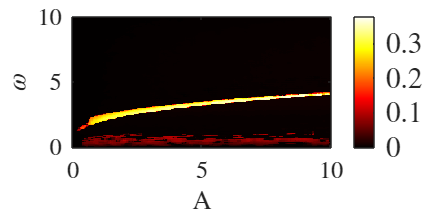


figure
imagesc(xd,yd,medfilt2(cd, [5 5]));
xlabel('A','interpreter','latex','FontSize', 24);
ylabel('$\omega$','interpreter','latex','FontSize', 24);
set(gcf, 'Position', [1 100 1280 640]);
set(gca,'FontSize',20, 'YDir', 'normal');
set(gca,'TickLabelInterpreter','latex');
c = colorbar;
set(c.Label,'String', "LLE",'Interpreter','latex','FontSize', 20);
set(c,'TickLabelInterpreter','latex', 'FontSize',24);
colormap("hot");


%% Call LLE2D() with user-defined arguments
% Syntax is ("Name", Value) pair
% Order of pairs doesn't matter
[xd, yd, cd] = duffCUDA.LLE2D("tMax", 500, ...
                              "nPts", 100, ...
                              "NT", 0.4, ...
                              "h", 0.01, ...
                              "LLE_eps", 1e-3, ...
                              "intCon", [0, 1, 0], ...
                              "ranges", [0, 10; ...
                                         0, 10], ...
                              "indicesOfMutVars", [3, 4], ...
                              "writableVar", 3, ...
                              "maxValue", 1000, ...
                              "transient", 500, ...
                              "values", [0.02, -1, 1, 3, 1]);

Inputs validation & parsing completed... 
Starting CUDA... 
LLE2D
nPtsLimiter : 10000
Amount of iterations 1: 
Progress: 100.000000
Computations done... 
Building matlab-covinient output 
All done!!!

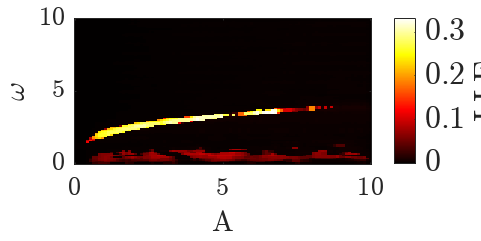


figure
imagesc(xd,yd,medfilt2(cd, [5 5]));
xlabel('A','interpreter','latex','FontSize', 24);
ylabel('$\omega$','interpreter','latex','FontSize', 24);
set(gcf, 'Position', [1 100 1280 640]);
set(gca,'FontSize',20, 'YDir', 'normal');
set(gca,'TickLabelInterpreter','latex');
c = colorbar;
set(c.Label,'String', "LLE",'Interpreter','latex','FontSize', 20);
set(c,'TickLabelInterpreter','latex', 'FontSize',24);
colormap("hot");


%% Call LLE2D() with user-defined arguments
% Syntax is (Name=Value) pair
% Order of pairs doesn't matter
[xd, yd, cd] = duffCUDA.LLE2D(tMax = 500, ...
                              nPts = 100, ...
                              NT = 0.4, ...
                              h = 0.01, ...
                              LLE_eps = 1e-3, ...
                              intCon = [0, 1, 0], ...
                              ranges = [0, 10; ...
                                        0, 10], ...
                              indicesOfMutVars = [3, 4], ...
                              writableVar = 3, ...
                              maxValue = 1000, ...
                              transient = 500, ...
                              values = [0.02, -1, 1, 3, 1]);

Inputs validation & parsing completed... 
Starting CUDA... 
LLE2D
nPtsLimiter : 10000
Amount of iterations 1: 
Progress: 100.000000
Computations done... 
Building matlab-covinient output 
All done!!!


figure
imagesc(xd,yd,medfilt2(cd, [5 5]));
xlabel('A','interpreter','latex','FontSize', 24);
ylabel('$\omega$','interpreter','latex','FontSize', 24);
set(gcf, 'Position', [1 100 1280 640]);
set(gca,'FontSize',20, 'YDir', 'normal');
set(gca,'TickLabelInterpreter','latex');
c = colorbar;
set(c.Label,'String', "LLE",'Interpreter','latex','FontSize', 20);
set(c,'TickLabelInterpreter','latex', 'FontSize',24);
colormap("hot");


%% Call LLE2D() with user-defined arguments and global arguments
% Any number of arguments can be defined or omited (global are used) 
% Both ("Name", Value) and (Name=Value) syntaxes are supported
[xd, yd, cd] = duffCUDA.LLE2D("ranges", [0, 10; 0, 10], nPts=100);

Inputs validation & parsing completed... 
Starting CUDA... 
LLE2D
nPtsLimiter : 10000
Amount of iterations 1: 
Progress: 100.000000
Computations done... 
Building matlab-covinient output 
All done!!!


figure
imagesc(xd,yd,medfilt2(cd, [5 5]));
xlabel('A','interpreter','latex','FontSize', 24);
ylabel('$\omega$','interpreter','latex','FontSize', 24);
set(gcf, 'Position', [1 100 1280 640]);
set(gca,'FontSize',20, 'YDir', 'normal');
set(gca,'TickLabelInterpreter','latex');
c = colorbar;
set(c.Label,'String', "LLE",'Interpreter','latex','FontSize', 20);
set(c,'TickLabelInterpreter','latex', 'FontSize',24);
colormap("hot");